Video processing complete: 0%
Video processing complete: 1%
Video processing complete: 2%
Video processing complete: 3%
Video processing complete: 4%
Video processing complete: 5%
Video processing complete: 6%
Video processing complete: 7%
Video processing complete: 8%
Video processing complete: 9%
Video processing complete: 10%
Video processing complete: 11%
Video processing complete: 12%
Video processing complete: 13%
Video processing complete: 14%
Video processing complete: 15%
Video processing complete: 16%
Video processing complete: 17%
Video processing complete: 18%
Video processing complete: 19%
Video processing complete: 20%
Video processing complete: 21%
Video processing complete: 22%
Video processing complete: 23%
Video processing complete: 24%
Video processing complete: 25%
Video processing complete: 26%
Video processing complete: 27%
Video processing complete: 28%
Video processing complete: 29%
Video processing complete: 30%
Video processing complete: 31%
Video processing c

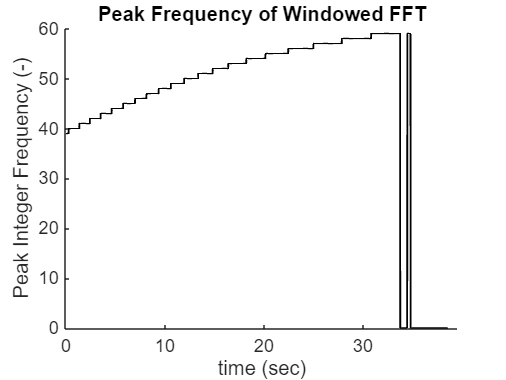

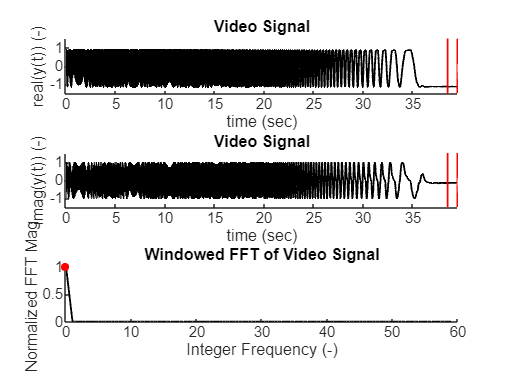

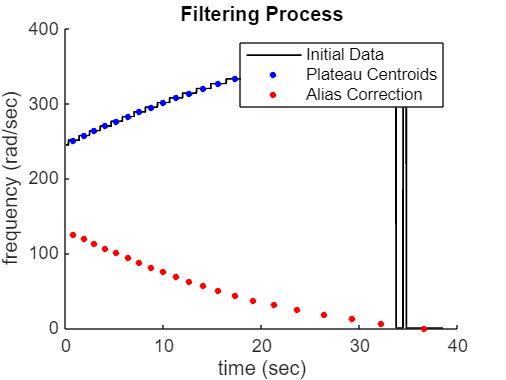

ans =          0    1.0756    2.1512    3.2518    4.3857    5.5614    6.7370    7.9293    9.1634   10.4474   11.8231   13.2656   14.7831   16.4757   18.3517   20.4695   22.8875   25.5890   28.4989   31.4422   35.8446


fname = 'fidgetspinnervideo.mov';

Video width (pixels): 1080
Video height (pixels): 1920
Video processing complete: 0%


Video processing complete: 1%
Video processing complete: 2%
Video processing complete: 3%
Video processing complete: 4%
Video processing complete: 5%
Video processing complete: 6%
Video processing complete: 7%
Video processing complete: 8%
Video processing complete: 9%
Video processing complete: 10%
Video processing complete: 11%
Video processing complete: 12%
Video processing complete: 13%
Video processing complete: 14%
Video processing complete: 15%
Video processing complete: 16%
Video processing complete: 17%
Video processing complete: 18%
Video processing complete: 19%
Video processing complete: 20%
Video processing complete: 21%
Video processing complete: 22%
Video processing complete: 23%
Video processing complete: 24%
Video processing complete: 25%
Video processing complete: 26%
Video processing complete: 27%
Video processing complete: 28%
Video processing complete: 29%
Video processing complete: 30%
Video processing complete: 31%
Video processing complete: 32%
Video processing 

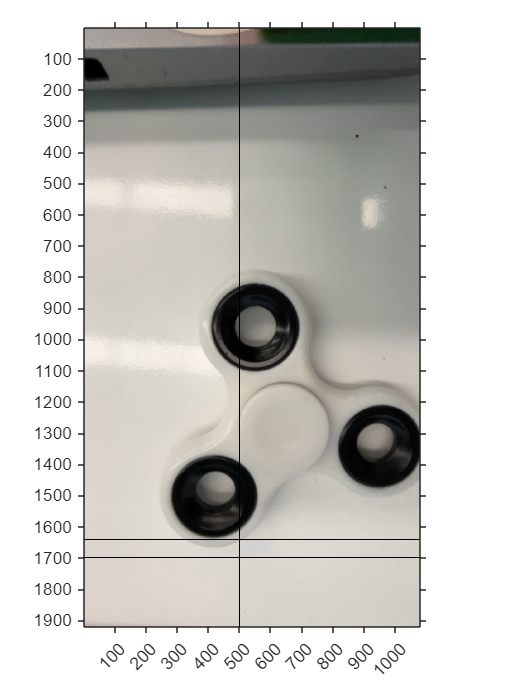

y =    90.6971  210.3603  225.3542   43.6645  225.2647  222.5087   37.1803  226.9445  211.1610   68.0724  226.2404  183.4821  116.1294  225.1613  148.8531  166.1636  224.2850  108.7306  198.2130  223.4308   66.4991  215.0854  222.6249   40.5360  224.2513  220.6057   34.7367  225.4004  215.6244   45.6053  224.8622  204.2952   73.7069  224.2081  185.8396  104.8305  223.4821  166.1751  135.6083  223.3112  141.8682  163.0477  222.8533  117.3741  181.8984  222.4058   95.6794  197.9804  222.1016   78.3770


Fs = 59.9671

%window_bounds: a MATLAB struct that indicates the boundaries of the
% window to use for averaging the pixel value.
window_bounds = struct();
window_bounds.top = 1640;
window_bounds.bottom = 1700;
window_bounds.left = 500;
window_bounds.right = 600;
%show_image: a boolean (0 or 1) that determines whether or not the video
% of the fidget spinner is displayed during processing
% set show_image to 1 if you are still trying to figure out
% the boundaries of the window to use
% set show_image to 0 to process the video faster
show_image = 1;
%Converts the video file of a fidget spinner to a time signal
%by computing the average pixel value in a window for each frame
%OUTPUTS:
%y: a list of the averaged pixel value in the window
%Fs: framerate of the video
[y,Fs] = video_to_signal(fname,window_bounds,show_image)

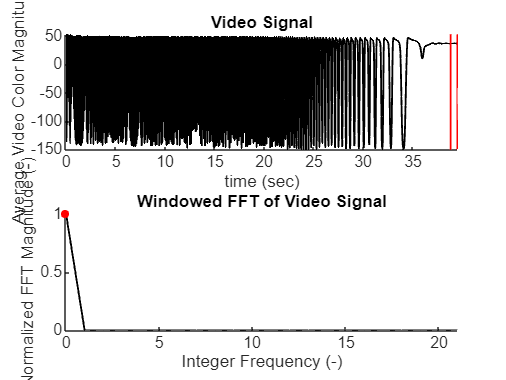

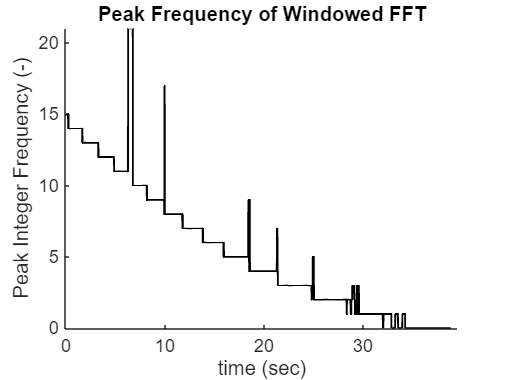

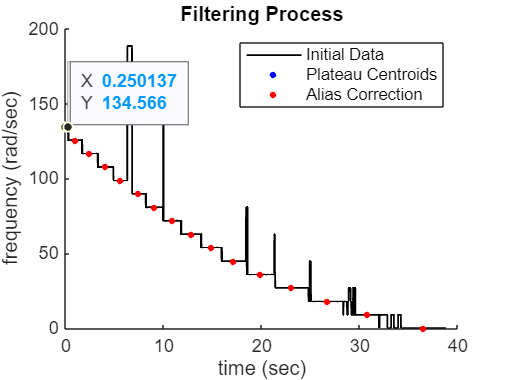

fname_save = 'data.mat'; %should be a .mat file
save(fname_save,'y','Fs'); %save results from video_to_signal
S = load(fname_save,'y','Fs'); %load results from save file
y = S.y; Fs = S.Fs; %place values in variables y and Fs

%T_window: width of FFT window (in seconds) .7 is usually good
T_window = .7;
%q: a parameter used to filter which portions of frequency curve to use
% (filter is by width of flat portions of curve)
% value should be in interval [0,1]
% values closer to 1 are most "exclusive".
% .6 is a pretty good value to choose
q = .6;
%showAnalysis: boolean that turns visualization on/off
showAnalysis = 1;
%uses FFT and some filtering tricks to extract angular velocity of fidget
%spinner as a function of time
%OUTPUTS:
%tlist: list of times for measured values of angular frequency
%omega_list: measured value of angular frequency
[tlist,freq_list] = fidget_spinner_FFT(y,Fs,T_window,q,showAnalysis);


%NOTE: you should choose a different file name than your other save file!!!
fname_save2 = 'frequencies.mat'; %should be a .mat file
save(fname_save2,'tlist','freq_list'); %save results from fidget_spinner_FFT
S2 = load(fname_save2,'tlist','freq_list'); %load results from save file
tlist = S2.tlist; freq_list = S2.freq_list; %unpack loaded variables

tlist = S2.tlist

tlist =          0    1.5092    3.1184    4.6109    6.5036    8.0961    9.9054   11.8398   13.9160   16.2172   18.9687   22.1288   25.7224   29.8163   35.5778


freqlist = S2.freq_list

freqlist =   125.5949  116.6238  107.6528   98.6817   89.7106   80.7396   71.7685   62.7974   53.8264   44.8553   35.8843   26.9132   17.9421    8.9711         0




freq_true = freqlist ./ 3

freq_true =    41.8650   38.8746   35.8843   32.8939   29.9035   26.9132   23.9228   20.9325   17.9421   14.9518   11.9614    8.9711    5.9807    2.9904         0


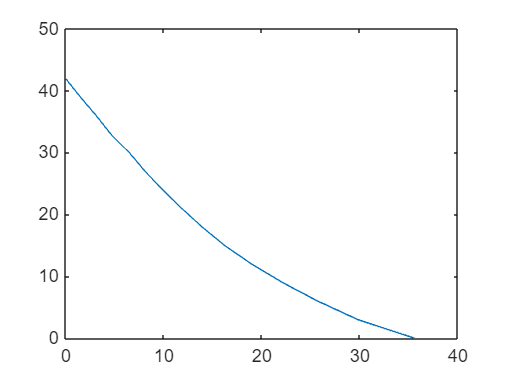

figure;
plot(tlist, freq_true)


freq_midpoints = zeros(14,1)

freq_midpoints =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for index = 1:14
    freq_midpoints(index) = (freq_true(index)+freq_true(index+1))/2;
end

angular_acc = zeros(14, 1)

angular_acc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for index = 1:14
    angular_acc(index) = (freq_true(index+1)-freq_true(index)) / (S2.tlist(index+1)-S2.tlist(index));
end

p = polyfit(freq_midpoints, angular_acc, 2)

p =     0.0006   -0.0640   -0.4070


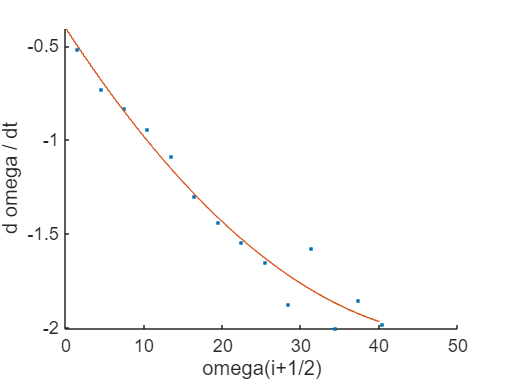


figure;
scatter(freq_midpoints, angular_acc, "."); hold on;
xlabel("omega(i+1/2)")
ylabel("d omega / dt")
omega = linspace(0,40,100);
plot(omega, p(1)*omega.^2 + p(2).*omega + p(3));



f = @(t_in,omega_in) p(1)*omega_in^2 + p(2)*omega_in + p(3);
[t_list, ode45_freq_list] = ode45(f, [0, 40], 7)

t_list =          0
    0.4266
    0.8531
    1.2797
    1.7062
    2.7062
    3.7062
    4.7062
    5.7062
    6.7062


ode45_freq_list =     7.0000
    6.6525
    6.3131
    5.9817
    5.6583
    4.9301
    4.2430
    3.5949
    2.9844
    2.4095


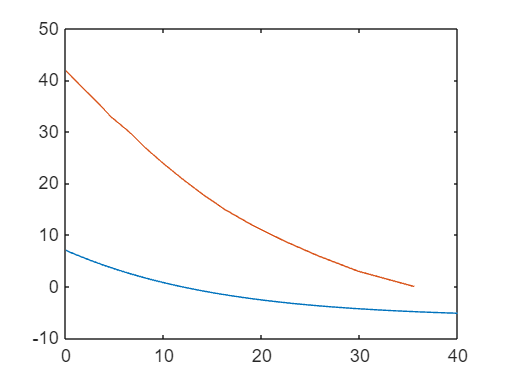

figure;
plot(t_list, ode45_freq_list); hold on;
plot(tlist, freq_true)

% plot(linspace(0,3,100), 10*exp(-2*linspace(0,3,100)));